clear; clc; close all; fclose all;format long;
ENABLE_DELAY_CH = true;
ENABLE_MULTIPATH_CH = true;
IFFT_FFT_LOOPBACK = false;      % Skip DUC,DDC in MATLAB
CFR_EN = false;                  % Enable CFR
CH_AVG = false;                 % Average channel estimate accross entire packet
addpath('../');

# **OFDM Parameters:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read OFDM Parameters from Info file from SW program
file = fopen('../../Testing/OfdmInfo1.txt','r');
nfft = fscanf(file,"%d,",1);                % Size of FFT, number of subcarriers in OFDM
BW = fscanf(file,"%d,",1); BW = BW*1000;    % Bandwidth = complex FS
cp_len = fscanf(file, "%d,", 1);            % Cyclic Prefix length in samples
M = fscanf(file,"%d,", 1);                  % Modulation Order
ZP_density = fscanf(file,"%d,", 1);         % Zero Padded Pilot Density
symbol_guard_ms = fscanf(file,"%d,",1);     % Symbol guard band in ms
frame_guard_ms = fscanf(file,"%d,",1);      % Frame guard band in ms
ofdm_symbols = fscanf(file,"%d,",1);        % Number of OFDM symbols in a Frame
Fc = fscanf(file,"%d,",1); Fc = Fc * 1000;  % Center frequency of OFDM signal
tx_scale = fscanf(file,"%d,",1);            % Frequency domain digital gain
ifft_gain = fscanf(file,"%f,",1);           % Ifft scalar gain
sync_gain = fscanf(file,"%f",1);            % Extra Sync Symbol gain
fclose('all');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fixed values
ZC_root = 13;                               % Zadoff-Chu root index
ZC_length = nfft/2;                         % Zadof-Chu length
sync_samples_early = 0;                     % Number of samples to synchronize early
pilot_density = 0.5;                       % Pilot carrier to data carrier density
DAC_FS = 10000000;                          % Sample frequency of the DAC
nfft_p = 32*nfft;                            % FFT size for plotting spectrum
Delay_samples = nfft/2; % Baseband samples of Delay channel to exercise the synchronizer
channel_scale = 1;
bit_resolution = 14;                        % Resolution of DAC and ADC
cfr_clipping_ratio = 0.6;                   % Crest factor reduction clipping ratio
cfr_filt_order = 256;                       % CFR LPF FIR Filter order

# **Calculated OFDM Parameters:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Parameters calculated from above configurable parameters
rep = 1/pilot_density;
first_pilot_carrier = ceil(nfft*ZP_density/100/2);
last_pilot_carrier = nfft-first_pilot_carrier;
zp_index1 = [1:first_pilot_carrier-1,last_pilot_carrier+1:nfft];
pilot_index = first_pilot_carrier:rep:last_pilot_carrier;
data_index = 1:nfft;
data_index([pilot_index,zp_index1]) = [];
scs = BW/nfft;
num_data_bits = length(data_index)*ofdm_symbols;
pilot_carriers = length(pilot_index);
data_carriers = length(data_index);
ind = find(data_index==nfft/2);
if (ind) % Set data DC subcarrier as ZP subcarrier
    data_index(ind) = [];
    data_carriers = data_carriers-1;
else
    %error('DC subcarrier is a pilot')
    warning('DC subcarrier is a pilot')
    ind = find(pilot_index==nfft/2);
    pilot_index(ind) = [];
    pilot_carriers = pilot_carriers-1;
end

zp_index = [1:first_pilot_carrier-1 nfft/2 last_pilot_carrier+1:nfft];
zp_carriers = length(zp_index);
n_packed = nfft*M;
Fs = BW; % Sample frequency (complex) = bandwidth
Interp_val = DAC_FS/Fs; % Interpolation value
if (ENABLE_DELAY_CH)
    Delay_interp = Delay_samples*Interp_val;
else
    Delay_interp = 0;
end
Ts = 1/Fs; % Sampling period
t = 0:Ts:(nfft+cp_len-1)*Ts; % Time vector for 1 OFDM symbol
t_up = 0:1/DAC_FS:((nfft+cp_len)*(ofdm_symbols+1)*Interp_val-1)*1/DAC_FS;
t_up_length = length(t_up);
t_up_rx = 0:1/DAC_FS:(t_up_length+Delay_interp*2)*1/DAC_FS-1/DAC_FS; % time vector adding delay
F = (-nfft_p/2:nfft_p/2-1)/nfft_p*Fs; % Plotting baseband spectrum
F_up = (-nfft_p/2:nfft_p/2-1)/nfft_p*DAC_FS; % Plotting DUC spectrum
xilinx_cic_filter_latency = (Interp_val-1)/DAC_FS;

# **QAM Modulation:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create data vector
data = randsrc(data_carriers,ofdm_symbols,0:M-1);
mod_data = data;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Generate random pilot data again
rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% QAM Modulation (frequency domain)
qpsk_mod_data = qammod(data,M);
reference_pilot = qammod(pilot_data,M);
zp_carrier = complex(0,0);
nfilt = 1024;

# **SYNCHRONIZATION:**

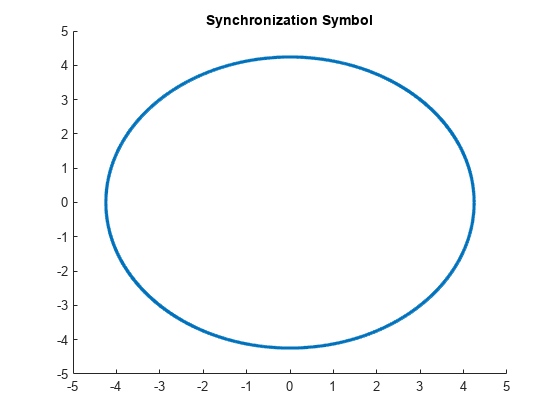

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create Zadoff-Chu sequence
% Set ZC sequence to be 50% ZC and 50% ZP
sync_tx = log2(M)/sqrt(2)*exp(-1i*pi*ZC_root*(1:ZC_length).*((1:ZC_length)+1)/ZC_length); % ZC sequence
sync_tx_zp = [zeros(1,(nfft-ZC_length)/2),sync_tx,zeros(1,(nfft-ZC_length)/2)]; % Add ZP
sync_tx_time = ifft(ifftshift(sync_tx_zp),nfft); % ZC sequence in the time domain

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),scatter(real(sync_tx),imag(sync_tx),'.'),title('Synchronization Symbol')

# **CARRIER ALLOCATION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT carriers of data,pilot and ZP carriers
carriers = zeros(nfft,ofdm_symbols);
carriers(pilot_index,:) = reference_pilot;
carriers(data_index,:) = qpsk_mod_data;
carriers(zp_index,:) = zp_carrier;
carriers_zc = horzcat(sync_tx_zp.',carriers); % Allocate ZC symbol
carriers_zc = carriers_zc*tx_scale;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate power in dBFS
dBFS_tx_freq = zeros(ofdm_symbols+1,1);
full_scale = (2^(16-1))^2 * nfft*2;
%carriers_zc(:,1) = complex((2^13),(2^13));
for i=1:ofdm_symbols+1
    i_square = real(carriers_zc(:,i)).^2;    q_square = imag(carriers_zc(:,i)).^2;
    i_sum = sum(i_square);    q_sum = sum(q_square);
    carriers_pow = i_sum + q_sum;
    dBFS_tx_freq(i) = 10*log10(carriers_pow/full_scale);
end
figure(),table(dBFS_tx_freq)

ans = 17×1 table
      dBFS_tx_freq   
    _________________

    -3.48982354842075
     2.22856837920182
     2.24243918249415
     2.23790452190798
      2.3190600854414
      2.2406762659613
     2.35478441104577
     2.24646602081605
     2.26704516797071
     2.17698553611816
     2.25325285536835
     2.21135754907233
     2.29872651654208
     2.23765245743599
     2.21921212309806
     2.26228550138167


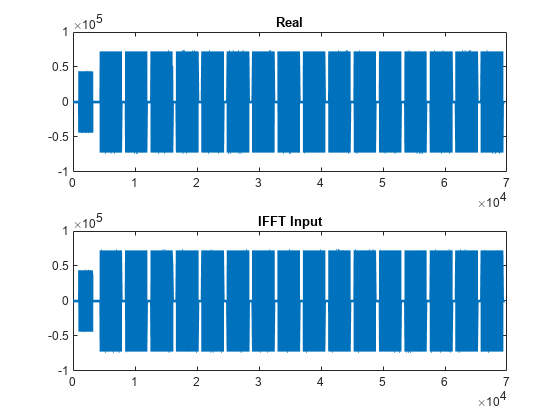


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plotting
carriers_plot = reshape(carriers_zc,[1 (ofdm_symbols+1)*nfft]);
figure(),subplot(2,1,1),plot(real(carriers_plot),'LineWidth',2),title('Real')
subplot(2,1,2),plot(imag(carriers_plot),'LineWidth',2),title('IFFT Input')

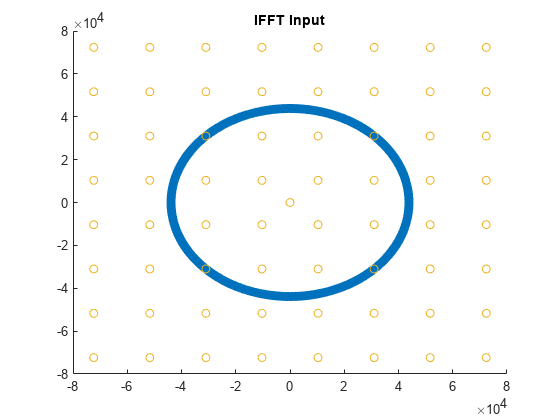

figure(),scatter(real(carriers_zc),imag(carriers_zc)),title('IFFT Input')

# **IFFT:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Ifftshift to reorder carriers in correct order for IFFT
ifft_sub_carriers = zeros(nfft,ofdm_symbols+1);
for i=1:ofdm_symbols+1 % do in loop so that ifftshift works per symbol instead of per frame
    ifft_sub_carriers(:,i) = ifft(ifftshift(carriers_zc(:,i)),nfft);
    if (i == 1) % Synchronization symbol extra gian
        ifft_sub_carriers(:,i) = ifft_sub_carriers(:,i)*sync_gain;
    end
end
ifft_sub_carriers = ifft_sub_carriers * ifft_gain;

# **CP INSERTION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cyclic Prefix (copy end of symbol to beginning
cp_start = nfft-cp_len;
cp = ifft_sub_carriers(cp_start+1:end,:);
cp(:,1) = complex(0,0); % No CP for synchronization symbol, set as GP
ofdm_tx_signal_par = zeros(nfft+cp_len,ofdm_symbols+1);
for i=1:ofdm_symbols+1
    if (i == 1) % Synchronization symbolk
        ofdm_tx_signal_par(:,1) = [ifft_sub_carriers(:,1);cp(:,1)];
    else
        ofdm_tx_signal_par(:,i) = [cp(:,i);ifft_sub_carriers(:,i)];
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate power in dBFS
dBFS_baseband = zeros(ofdm_symbols+1,1); PAPR_dB = zeros(ofdm_symbols+1,1);
%ofdm_tx_signal_par(:,1) = complex(2^13,2^13);
full_scale = (2^(bit_resolution-1))^2 * (nfft+cp_len)*2;
for i=1:ofdm_symbols+1
    % Average dBFS Power
    carriers_pow = i_sum + q_sum;
    carriers_pow = sum(abs(ofdm_tx_signal_par(:,i)).^2);
    dBFS_baseband(i) = 10*log10(carriers_pow/full_scale);

    % Peak to Average Power Ratio (PAPR)
    peak_power = max(abs(ofdm_tx_signal_par(:,i))).^2;
    average_power = mean(abs(ofdm_tx_signal_par(:,i)).^2);
    PAPR_dB(i) = 10*log10(peak_power/average_power);
end
Headroom_dBFS = PAPR_dB + dBFS_baseband;
figure(),table(dBFS_baseband,PAPR_dB,Headroom_dBFS)

ans = 17×3 table
      dBFS_baseband          PAPR_dB           Headroom_dBFS  
    _________________    ________________    _________________

    -33.8355016203757    4.77963234019705    -29.0558692801787
    -33.8762528483653    9.77460760349773    -24.1016452448675
    -33.8276980782233    9.65799224850917    -24.1697058297142
    -33.8330528475888    9.30910014752848    -24.5239527000603
    -33.7710587993827     9.5213549233392    -24.2497038760435
    -33.8142157046953    10.8454222021357    -22.9687935025596
    -33.7261273280043    10.1224592117181    -23.6036681162862
    -33.8106153170187    9.08953776072361    -24.7210775562951
     -33.809595855323    9.20112103201912    -24.6084748233039
    -33.8770696340522    9.75598755498117    -24.1210820790711
    -33.8193957586377    9.32732366939645    -24.4920720892412
    -33.8876036646001    9.30711784178987    -24.580485822810

if (max(max(abs(ofdm_tx_signal_par))) >= (2^(bit_resolution-1)))
    warning('Signal clipping');
else
    max(max(abs(ofdm_tx_signal_par)))/2^(bit_resolution-1)
end

ans =    0.100479004287281


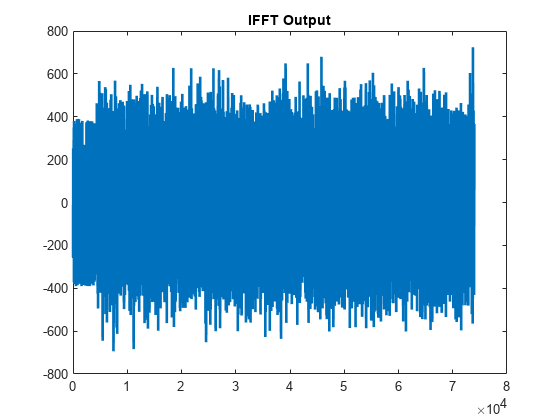


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot MATLAB vs IFFT output from SW
ofdm_tx_signal_re = reshape(ofdm_tx_signal_par,[1 (ofdm_symbols+1)*(nfft+cp_len)]);
figure(),plot(real(ofdm_tx_signal_re),'LineWidth',2),title('IFFT Output')

# **Parallel to Serial:**

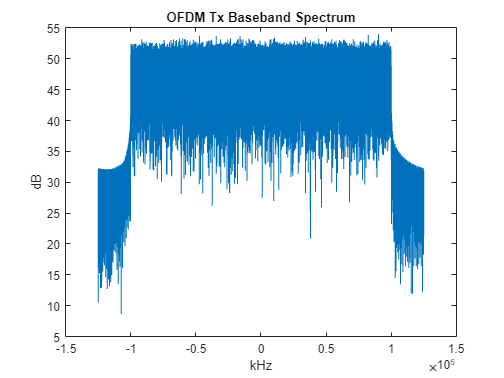

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Convert into vector of time domain samples
ofdm_tx_signal_ser = reshape(ofdm_tx_signal_par,[(nfft+cp_len)*(ofdm_symbols+1) 1]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot MATLAB baseband spectrum
figure(),plot(F,10*log10(abs(fftshift(fft(ofdm_tx_signal_ser,nfft_p))))),title('OFDM Tx Baseband Spectrum'),xlabel('kHz'),ylabel('dB')

# **DUC:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Perform DUC with matlab function
[ofdm_duc_signal, coef] = interp(ofdm_tx_signal_ser,Interp_val,10,1);
ofdm_duc_signal = ofdm_duc_signal.';

# **Crest Factor Reduction (CFR):**

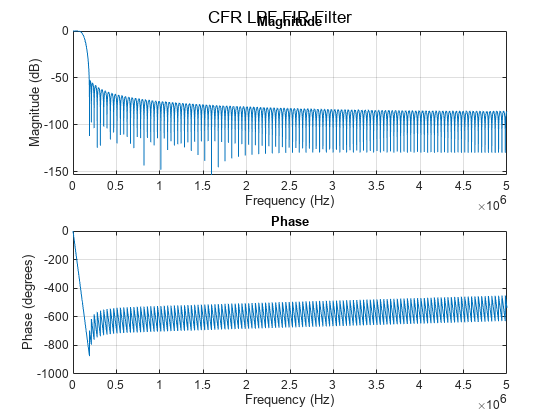

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Use clipping and LPF filtering method
peak_i = max(real(ofdm_duc_signal)); peak_q = max(imag(ofdm_duc_signal));
if (peak_i < peak_q)
    peak = peak_q;
else
    peak = peak_i;
end
ofdm_duc_cfr_signal = complex(sign(real(ofdm_duc_signal)).*min(abs(real(ofdm_duc_signal)),cfr_clipping_ratio*peak) ...
    ,sign(imag(ofdm_duc_signal)).*min(abs(imag(ofdm_duc_signal)),cfr_clipping_ratio*peak));
Wn = 1/Interp_val; % Normalized cutoff frequency
h_ideal = sin(Wn*pi*(-cfr_filt_order/2:cfr_filt_order/2))./(pi*(-cfr_filt_order/2:cfr_filt_order/2)); % Ideal lowpass impulse response
h_ideal(cfr_filt_order/2+1) = 1/Interp_val; % Get rid of divide by 0 value (NaN)
h = h_ideal .* kaiser(cfr_filt_order+1,5)'; % Window
h = h/sum(h); % Normalize
gd = grpdelay(h);
ofdm_duc_cfr_signal = [ofdm_duc_cfr_signal,zeros(1,gd(1))];
ofdm_duc_cfr_signal = complex(filter(h,1,real(ofdm_duc_cfr_signal)),filter(h,1,imag(ofdm_duc_cfr_signal)));
ofdm_duc_cfr_signal = ofdm_duc_cfr_signal(ceil(gd(end))+1:end); % Remove group delay caused by filter
freqz(h,1,nfft*4,DAC_FS),sgtitle('CFR LPF FIR Filter')

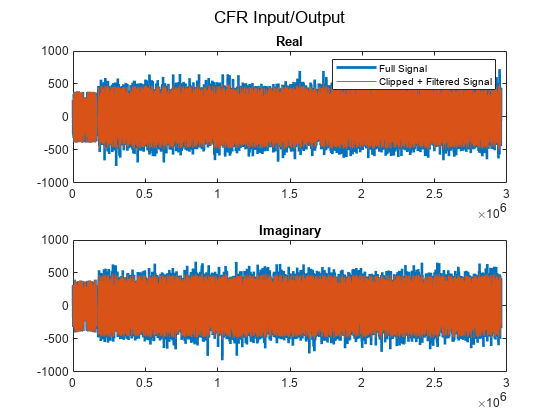


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),subplot(2,1,1),plot(real(ofdm_duc_signal),'LineWidth',2),hold on,plot(real(ofdm_duc_cfr_signal))
legend('Full Signal','Clipped + Filtered Signal'),title('Real'),subplot(2,1,2),plot(imag(ofdm_duc_signal),'LineWidth',2)
hold on,plot(imag(ofdm_duc_cfr_signal)),title('Imaginary'),sgtitle('CFR Input/Output')

# **IQ Mixer TX:**

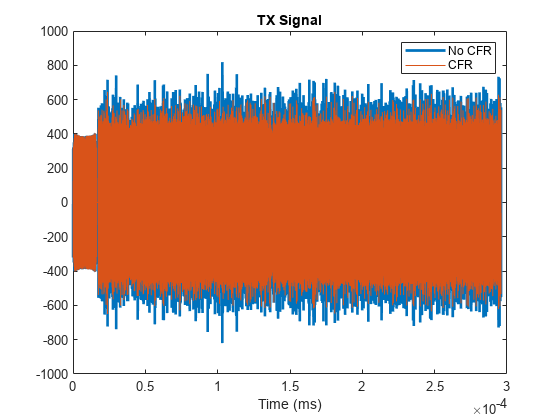

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Use oscillator at Fc for IQ mixer
ofdm_duc_signal_i = real(ofdm_duc_signal) .* cos(2*pi*Fc*t_up);
ofdm_duc_signal_q = imag(ofdm_duc_signal) .* -sin(2*pi*Fc*t_up);
ofdm_duc_signal_real = ofdm_duc_signal_i + ofdm_duc_signal_q;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Use oscillator at Fc for IQ mixer
ofdm_duc_cfr_signal_i = real(ofdm_duc_cfr_signal) .* cos(2*pi*Fc*t_up);
ofdm_duc_cfr_signal_q = imag(ofdm_duc_cfr_signal) .* -sin(2*pi*Fc*t_up);
ofdm_duc_cfr_signal_real = ofdm_duc_cfr_signal_i + ofdm_duc_cfr_signal_q;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot TX waveform
figure(),plot(t_up/1000,ofdm_duc_signal_real,'LineWidth',2),hold on,plot(t_up/1000,ofdm_duc_cfr_signal_real)
legend('No CFR','CFR'),xlabel('Time (ms)'),title('TX Signal')

if (CFR_EN)
    figure(),plot(t_up/1000,ofdm_duc_cfr_signal_real),xlabel('Time (ms)'),title('Tx Signal')
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate power in dBFS
dBFS_baseband = zeros(2,1); PAPR_dB = zeros(2,1); Headroom_dBFS = zeros(2,1);
full_scale = (2^(bit_resolution-1))^2 * (nfft+cp_len)*2;
carriers_pow = sum(abs(ofdm_duc_signal_real).^2);
dBFS_baseband(1) = 10*log10(carriers_pow/full_scale);
peak_power = max(abs(ofdm_duc_signal_real)).^2;
average_power = mean(abs(ofdm_duc_signal_real).^2);
PAPR_dB(1) = 10*log10(peak_power/average_power);
Headroom_dBFS(1) = PAPR_dB(1) + dBFS_baseband(1);
% CFR
carriers_pow = sum(abs(ofdm_duc_cfr_signal_real).^2);
dBFS_baseband(2) = 10*log10(carriers_pow/full_scale);
peak_power = max(abs(ofdm_duc_cfr_signal_real)).^2;
average_power = mean(abs(ofdm_duc_cfr_signal_real).^2);
PAPR_dB(2) = 10*log10(peak_power/average_power);
Headroom_dBFS(2) = PAPR_dB(2) + dBFS_baseband(2);
figure(),table(dBFS_baseband,PAPR_dB,Headroom_dBFS)

ans = 2×3 table
      dBFS_baseband          PAPR_dB          Headroom_dBFS  
    _________________    ________________    ________________

    -8.51649031647218    13.8417422596883    5.32525194321611
    -8.78982099231773    12.0978541156563    3.30803312333858


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if (CFR_EN)
    ofdm_duc_signal_real = ofdm_duc_cfr_signal_real;
end

# **Channel:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Check max
max(ofdm_duc_signal_real)

ans =      8.188299188598164e+02


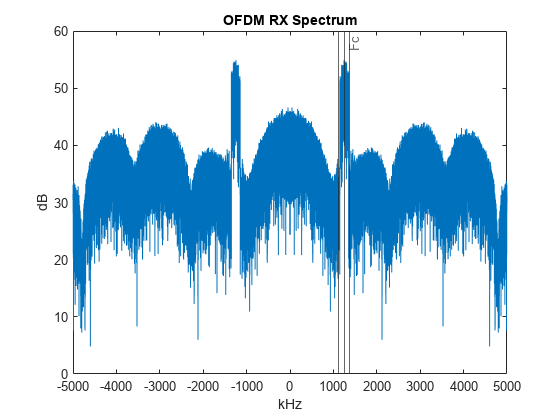


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AWGN + Multipath channel
SNR = 25;
ofdm_tx_signal_ch = awgn(ofdm_duc_signal_real,SNR,'measured');
multipath = [0 0.1 0.05 0 0.9 0 0 0.9 0.3 0.5 0.6 0.8 0 0 0.7];
if (ENABLE_MULTIPATH_CH)
    ofdm_tx_signal_ch = filter(multipath,1,ofdm_tx_signal_ch);
end
ofdm_tx_signal_ch = [ofdm_tx_signal_ch(end-Delay_interp+1:end),ofdm_tx_signal_ch ofdm_tx_signal_ch(end-2*Delay_interp+1:end-Delay_interp)];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot RX Spectrum
figure(),plot(F_up/1000,10*log10(abs(fftshift(fft(ofdm_tx_signal_ch,nfft_p))))),title('OFDM RX Spectrum'),xline([(Fc-BW/2)/1000 Fc/1000 (Fc+BW/2)/1000],'-',{' ','Fc',' '})
xlabel('kHz'),ylabel('dB')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Write real DAC samples to file for tb
% file = fopen('../Xilinx/Vivado/modules/sim/iq_mix_test_in.txt','wt');
% fprintf(file,"%d\n",int16(ofdm_duc_signal_real),length(ofdm_duc_signal_real));
% fclose('all');

# **IQ Mixer RX:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
i_ddc = ofdm_tx_signal_ch .* cos(2*pi*Fc*t_up_rx);
q_ddc = ofdm_tx_signal_ch .* -sin(2*pi*Fc*t_up_rx);
ddc_signal = complex(i_ddc,q_ddc);

# **DDC:**

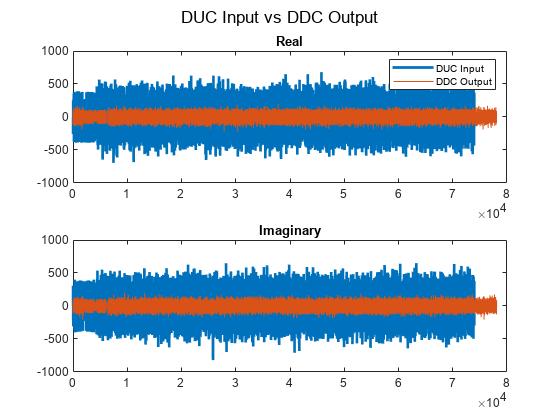

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Matlab decimate function - Ideal
ddc_base_signal_real = decimate(real(ddc_signal),Interp_val,4096,'Fir'); % Normal DDC
ddc_base_signal_imag = decimate(imag(ddc_signal),Interp_val,4096,'FIR');
ddc_base_signal = complex(ddc_base_signal_real,ddc_base_signal_imag);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Compare Matlab DDC output to DUC input
ddc_scale = 1.7;
figure(),subplot(2,1,1),plot(real(ofdm_tx_signal_ser),'LineWidth',2),hold on,plot(ddc_scale*real(ddc_base_signal)),title('Real')
legend('DUC Input','DDC Output'),subplot(2,1,2),plot(imag(ofdm_tx_signal_ser),'LineWidth',2),hold on,plot(ddc_scale*imag(ddc_base_signal)),title('Imaginary')
sgtitle('DUC Input vs DDC Output')

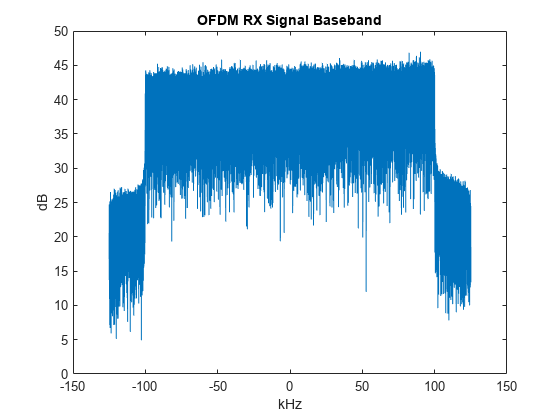


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),plot(F/1000,10*log10(abs(fftshift(fft(ddc_base_signal,nfft_p))))),title('OFDM RX Signal Baseband'),xlabel('kHz'),ylabel('dB')


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Skip DUC/DDC for Ideal RX signal
if (IFFT_FFT_LOOPBACK)
    ddc_base_signal = ofdm_tx_signal_ser;
end

# **SYNCHRONIZATION:**

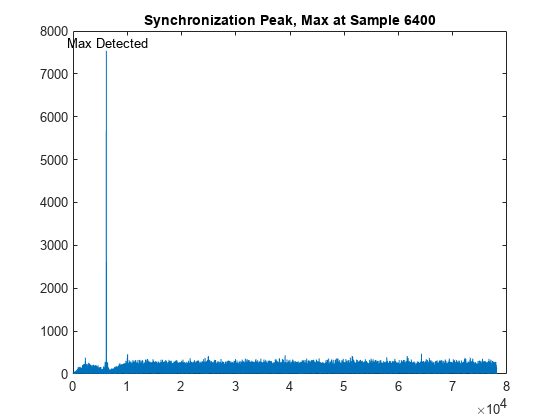

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Synchronization is detected in time domain
% Perform synchronization with filter insead of xcorr
% Define the matched filter as the time-reversed complex conjugate 
% of the ZC sequence.
%sync_tx_time = ifft_signal(:,1);
sync_coef = conj(fliplr(sync_tx_time)); % Matched filter
sync_corr_filt = abs(filter(sync_coef,1,ddc_base_signal)); 
[val,ind] = max(sync_corr_filt);
ind = ind+cp_len-sync_samples_early; % Remove GP from index

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Delete the Synchronization symbol and everything before it as well as
% everything after the last symbol
ofdm_rx_sync_signal = ddc_base_signal;
ofdm_rx_sync_signal([1:ind,ind+1+(nfft+cp_len)*ofdm_symbols:end]) = []; % Delete
% Check if signal is long enough
if (length(ofdm_rx_sync_signal) ~= (nfft+cp_len)*ofdm_symbols)
    tmp = zeros(1,(nfft+cp_len)*ofdm_symbols-length(ofdm_rx_sync_signal));
    ofdm_rx_sync_signal = [ofdm_rx_sync_signal tmp];
    warning('Deleted too much of signal')
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),plot(sync_corr_filt),hold on,text(ind,val,'Max Detected','HorizontalAlignment','center','VerticalAlignment','bottom')
title(['Synchronization Peak, Max at Sample ',num2str(ind)])

# **Serial to Parallel:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ofdm_rx_signal_par = reshape(ofdm_rx_sync_signal,[nfft+cp_len ofdm_symbols]);

# **CP Removal and CFO correction:**

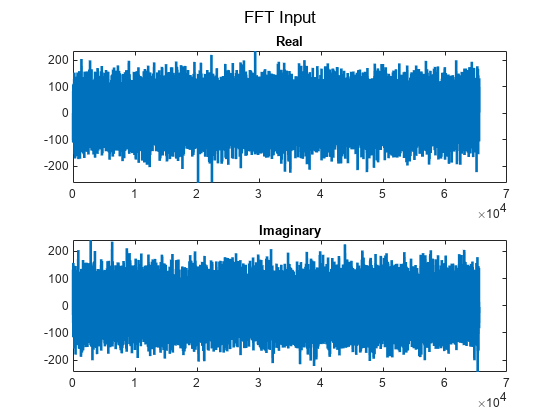

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Save and remove CP
cp_rm_signal = ofdm_rx_signal_par;
cp_rm_signal(1:cp_len,:) = []; % Remove CP
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CFO correction
ofdm_cfo_sig = [];
cfo_est = 0;
for i = 1:ofdm_symbols
    cp_cfo_begin = ofdm_rx_signal_par(1:cp_len,i); % Obtain CP at beginning of symbol
    cp_cfo_end = ofdm_rx_signal_par(nfft+1:end,i); % Obtain copy at end of symbol
    tmp = cp_cfo_end.*conj(cp_cfo_begin);          % Correlate
    sum_val = sum(tmp);
    tan_val = atan2(imag(sum_val),real(sum_val));
    normalized_cfo_est = 1*tan_val;
    cfo_est = normalized_cfo_est*scs;
    ofdm_cfo_sig(:,i) = cp_rm_signal(:,i).*(cos(cfo_est*t(1:nfft))+1i*sin(cfo_est*t(1:nfft)))';
end
%cp_rm_signal = ofdm_cfo_sig;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT input 
if (IFFT_FFT_LOOPBACK)
    cp_rm_signal_plot = reshape(cp_rm_signal,[1 ofdm_symbols*nfft]);
else
    cp_rm_signal_plot = 2*reshape(cp_rm_signal,[1 ofdm_symbols*nfft]);
end
figure(),subplot(2,1,1),plot(real(cp_rm_signal_plot),'LineWidth',2),title('Real')
subplot(2,1,2),plot(imag(cp_rm_signal_plot),'LineWidth',2),title('Imaginary'),sgtitle('FFT Input')

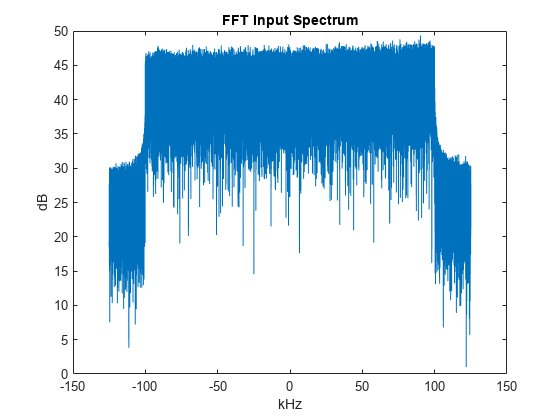

figure(),plot(F/1000,10*log10(abs(fftshift(fft(cp_rm_signal_plot,nfft_p))))),xlabel('kHz'),ylabel('dB'),title('FFT Input Spectrum')

# **Inverse CFR:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Inverse CFR
% if (CFR_EN)
%     max_i = max(max(real(cp_rm_signal))); max_q = max(max(imag(cp_rm_signal)));
%     if (max_i < max_q)
%         max_cfr = max_q;
%     else
%         max_cfr = max_i;
%     end
%     cp_rm_signal_save = cp_rm_signal;
%     cp_rm_signal(cp_rm_signal > max_cfr*cfr_clipping_ratio) = 1/cfr_clipping_ratio * cp_rm_signal(cp_rm_signal > max_cfr*cfr_clipping_ratio);
%     
%     cp_rm_signal_save = 2*reshape(cp_rm_signal_save,[1,ofdm_symbols*nfft]);
%     cp_rm_signal_cfr = 2*reshape(cp_rm_signal,[1,ofdm_symbols*nfft]);
%     ofdm_tx_signal_re_p = reshape(ifft_sub_carriers,[1,(ofdm_symbols+1)*nfft]);
%     ofdm_tx_signal_re_p(1:nfft) = [];
%     figure(),subplot(2,1,1),plot(real(ofdm_tx_signal_re_p),'LineWidth',3),hold on,plot(real(cp_rm_signal_save),'LineWidth',2),
%     plot(real(cp_rm_signal_cfr)),title('Real'),legend('TX','RX','CFR Correction')
%     subplot(2,1,2),plot(imag(ofdm_tx_signal_re_p),'LineWidth',3),hold on,plot(imag(cp_rm_signal_save),'LineWidth',2)
%     plot(imag(cp_rm_signal_cfr)),title('Imaginary'),sgtitle('FFT Input TX vs RX vs CFR Correction')
% end

# **FFT Output:**

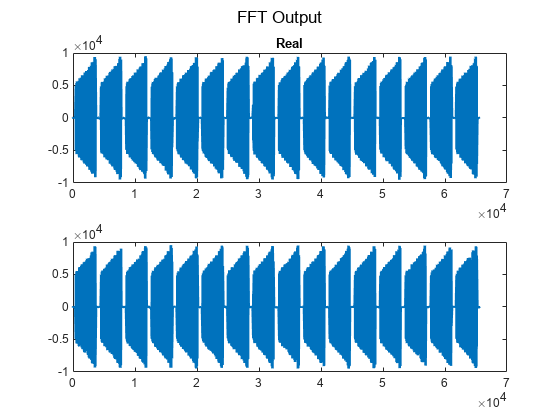

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFTshift same as TX (fftshift = Ifftshift)
fft_signal = zeros(nfft,ofdm_symbols);
for i=1:ofdm_symbols % Do fftshift per symbol
    fft_signal(:,i) = fftshift(fft(cp_rm_signal(:,i),nfft));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
if (IFFT_FFT_LOOPBACK)
    fft_signal_re = reshape(fft_signal,[1 ofdm_symbols*nfft]);
else
    fft_signal_re = 1.9*reshape(fft_signal,[1 ofdm_symbols*nfft]);
end
figure(),subplot(2,1,1),plot(real(fft_signal_re),'LineWidth',2),title('Real')
subplot(2,1,2),plot(imag(fft_signal_re),'LineWidth',2),sgtitle('FFT Output')

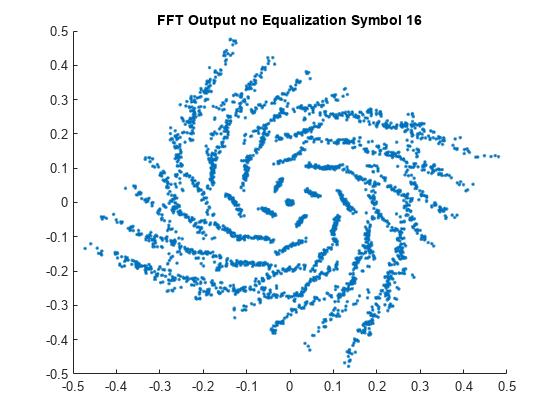


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot playback of packet per symbol
figure()

for i = 1:ofdm_symbols
    scatter(real(fft_signal(:,i)/tx_scale),imag(fft_signal(:,i)/tx_scale),'.')
    title(['FFT Output no Equalization Symbol ',num2str(i)])
    pause(0.1);
end

# **Equalization:**

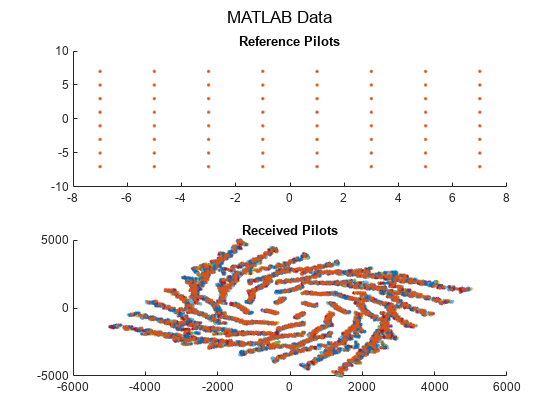

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get RX pilots
fft_signal_eq = fft_signal;
P_RX = fft_signal_eq(pilot_index,:); % Get Rx Pilots

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot RX Pilots
figure(),subplot(2,1,1),scatter(real(reference_pilot),imag(reference_pilot),'.'),title('Reference Pilots')
subplot(2,1,2),scatter(real(P_RX),imag(P_RX),'.'),title('Received Pilots'),sgtitle('MATLAB Data')

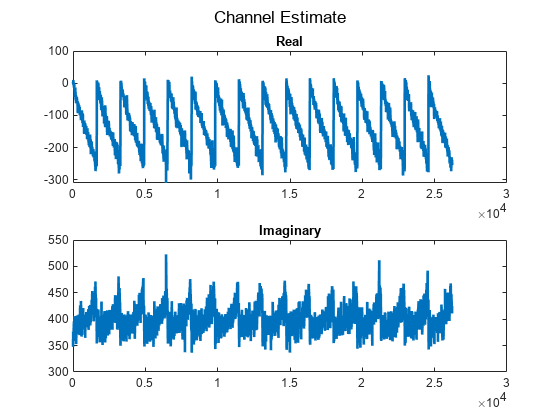

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get Channel Estimate
%P_RX = P_RX / tx_scale;
%reference_pilot = reference_pilot*tx_scale;
P_RX_re = real(P_RX); P_RX_im = imag(P_RX); P_re = real(reference_pilot); P_im = imag(reference_pilot);
P_RX_im = -P_RX_im; P_im = -P_im;
H = (P_RX_re.*P_re + P_RX_im.*P_im)./(P_re.^2 + P_im.^2) + 1i*(P_RX_im.*P_re - P_RX_re.*P_im)./(P_re.^2 + P_im.^2);
H_interp = interp1(pilot_index,H,1:nfft,'previous');
[a,b] = size(H_interp);
if (a==1)
    H_interp = H_interp.';
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Check if pilots wrap data
% Check if pilots wrap data
if (last_pilot_carrier ~= pilot_index(end))
    if (last_pilot_carrier-1 ~= pilot_index(end))
        if (last_pilot_carrier-2 ~= pilot_index(end))
            disp('Pilots do no wrap, setting last pilot to previous pilot')
            H_interp(data_index(end-2),:) = H_interp(data_index(end-3),:);
        end
        disp('Pilots do no wrap, setting last pilot to previous pilot')
        H_interp(data_index(end-1),:) = H_interp(data_index(end-2),:);
    end    
    disp('Pilots do no wrap, setting last pilot to previous pilot')
    H_interp(data_index(end),:) = H_interp(data_index(end-1),:);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Average channel estimates to reduce noise
if (CH_AVG)
    H_interp = repmat(mean(H_interp,2),1,ofdm_symbols);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Equalize data with channel estimates
H_ZF_re = real(H_interp); H_ZF_im = imag(H_interp);fft_re = real(fft_signal_eq);fft_im = imag(fft_signal_eq);
H_ZF_im = -H_ZF_im;
% Equalize
Z_EQ_ZF = (fft_re.*H_ZF_re + fft_im.*H_ZF_im)./(H_ZF_re.^2 + H_ZF_im.^2) + 1i*(fft_im.*H_ZF_re - fft_re.*H_ZF_im)./(H_ZF_re.^2 + H_ZF_im.^2);
fft_signal_eq([pilot_index,zp_index],:) = [];
Z_EQ_ZF([pilot_index,zp_index],:) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot channel estimate
H_plot = reshape(H,[1 ofdm_symbols*pilot_carriers]);
figure(),subplot(2,1,1),plot(real(H_plot),'LineWidth',2),title('Real')
subplot(2,1,2),plot(imag(H_plot),'LineWidth',2),title('Imaginary'),sgtitle('Channel Estimate')

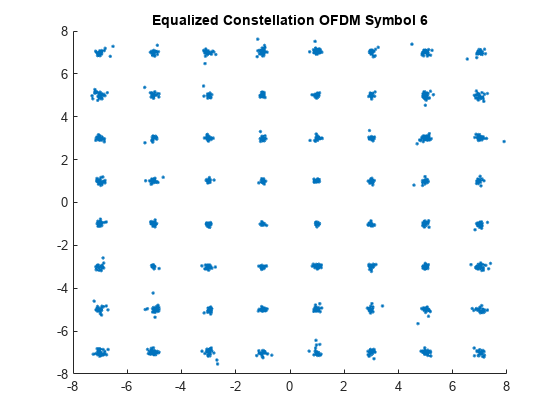


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot playback of frame per symbol
figure()

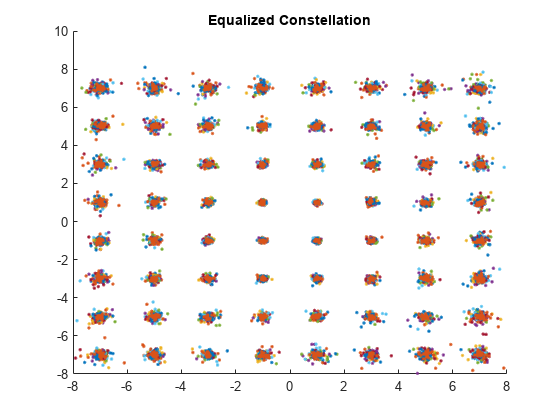

for i = 1:ofdm_symbols
    %subplot(3,1,1),scatter(real(fft_signal_eq),imag(fft_signal_eq),'.'),title('MATLAB no Equalization')
    scatter(real(Z_EQ_ZF(:,i)),imag(Z_EQ_ZF(:,i)),'.')
    title(['Equalized Constellation OFDM Symbol ',num2str(i)])
    pause(0.1)
end
figure(),scatter(real(Z_EQ_ZF),imag(Z_EQ_ZF),'.'),title('Equalized Constellation')

# **QAM Demodulation:**

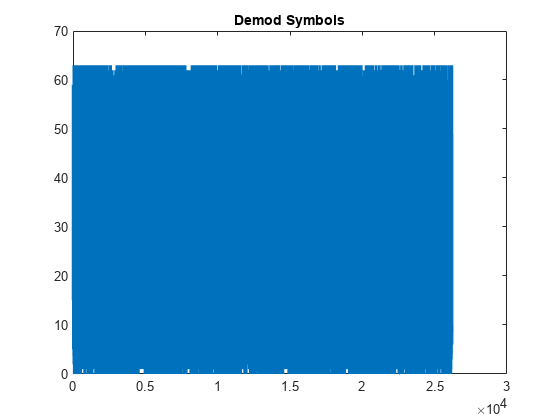

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Demod
demod_data = qamdemod(Z_EQ_ZF,M);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot 
demod_data_plot = reshape(demod_data,[1 ofdm_symbols*data_carriers]);
figure(),plot(demod_data_plot,'LineWidth',2),title('Demod Symbols')

# **Error Rate:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate symbol error rate
ser_mat = symerr(data, demod_data)/numel(data);

# **Analysis:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get EVM measurements
evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[mat_evm,mat_evm_pk] = evm(qpsk_mod_data,Z_EQ_ZF);

Equalization = "MATLAB";
SER = ser_mat;
AverageEVM = mat_evm;
PeakEVM = mat_evm_pk;
figure(),table(Equalization,SER,AverageEVM,PeakEVM)

ans = 1×4 table
    Equalization            SER                AverageEVM           PeakEVM     
    ____________    ____________________    ________________    ________________

      "MATLAB"      0.000152625152625153    2.19438044682011    20.6761888899269


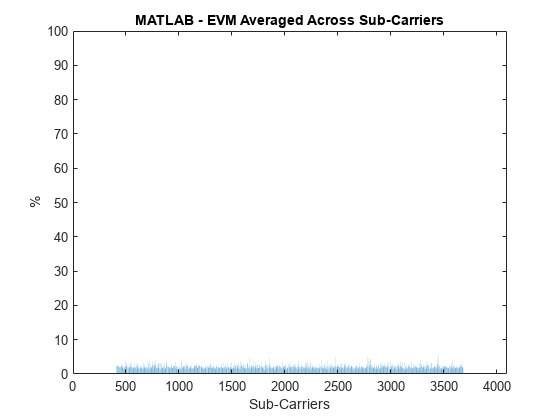

evm = comm.EVM(AveragingDimensions=2);
sw_evm = evm(qpsk_mod_data,Z_EQ_ZF);
y_lim = [0 100];
y1 = 1:nfft;
sw_evm_y = zeros(1,nfft);
sw_evm_y(data_index) = sw_evm;
figure(),bar(y1,sw_evm_y),title('MATLAB - EVM Averaged Across Sub-Carriers'),ax = gca; ax.YLim = y_lim;xlabel('Sub-Carriers'),ylabel('%')

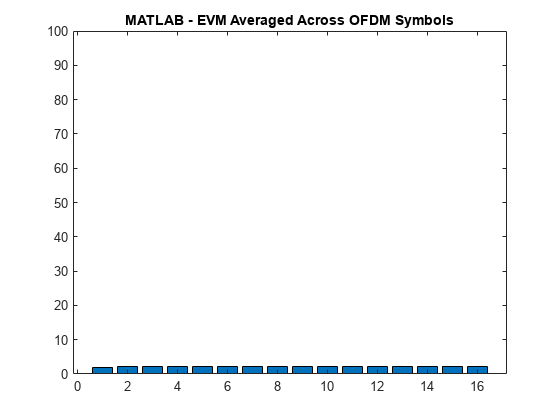


evm = comm.EVM(AveragingDimensions=1);
sw_evm = evm(qpsk_mod_data,Z_EQ_ZF);
y = 1:ofdm_symbols;
figure(),bar(y,sw_evm),title('MATLAB - EVM Averaged Across OFDM Symbols'),ax = gca; ax.YLim = y_lim;

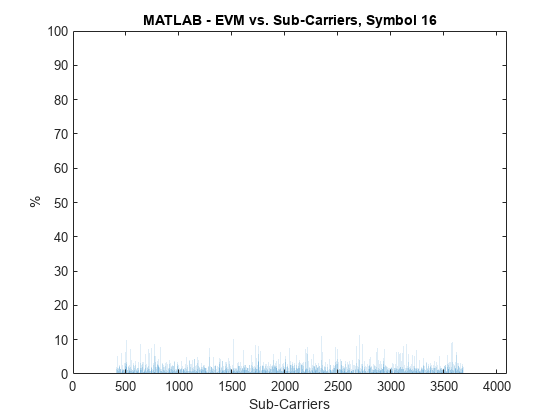


evm = comm.EVM(AveragingDimensions=2);
figure()
y_lim = [0 100];
y1 = 1:nfft;
sw_evm_y = zeros(1,nfft);
for i=1:ofdm_symbols
    sw_evm = evm(qpsk_mod_data(:,i),Z_EQ_ZF(:,i));
    sw_evm_y = zeros(1,nfft);
    sw_evm_y(data_index) = sw_evm;
    bar(y1,sw_evm_y),title(['MATLAB - EVM vs. Sub-Carriers, Symbol ',num2str(i)])
    ax = gca; ax.YLim = y_lim; xlabel('Sub-Carriers'),ylabel('%')
    pause(0.01)
end